clear variables

T=1/500; % Time constant
t=linspace(0,8*T,1e3);% time basis

x01=5e-2;% drop voltage over the capacitor at t=0
x02=2e-4; % current throughthe inductor at t=0

% transitionmatrix as time expression terms
tm11=exp(-500*t) -500*t.*exp(-500*t);
tm12=(-1000000*exp((-500*t))).*t;
tm21=(exp((-500*t))/4).*t;
tm22=(500*exp((-500*t))).*t + exp(-500*t);

x1=tm11*x01+tm12*x02;
x2=tm21*x01+tm22*x02;

subplot(221);plot(t,x1);xlabel('Time(sec.)');ylabel('x_1(t)');
title('First state variable');grid;hold

Current plot held


subplot(223);plot(t,x2);title('x_2(t)');xlabel('Time(sec.)');ylabel('x_2(t)');
title('Second state variable');grid;shg;hold

Current plot held


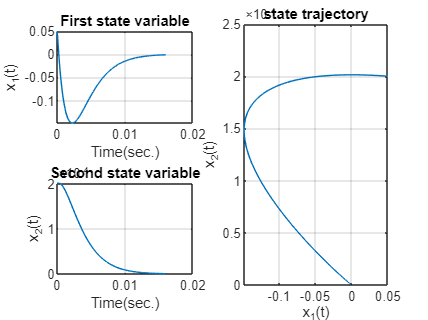

Current plot held


subplot(2,2,[2,4]);plot(x1,x2,'-');title('state trajectory');
xlabel('x_1(t)');ylabel('x_2(t)');grid;shg;hold